## **Àlgebra lineal -**

## **Mètodes directes de resolució de sistemes lineal**

A = [1 2 1; -2 7 3; 1 -1 10]

determinante

det(A)

inversa

inv(A)

rango

rank(A)

transpuesta

A'

norma 1

norm(A,1)

norma infinit

norm(A, 'inf')

norma 2

norm(A,2)
%eig calcula els valors propis
norma2 = sqrt(eig(A'*A))

## **Matrius definides**

Matriz de zeros

zeros(4)

Matriz de unos

ones(5)

Matriz identidad

eye(4)

Matriz donde los valores van de 5 a 5^2 y la suma de las finals y columass son las mismas

magic(5)

diagonal de la matriz

v = diag(A)

diag(v)

triangular de la matriz menor

tril(A)

triangular de la matriz menos uno

tril(A,-1)

 triangular de la matriz superior

triu(A)

triangular de la matriz menos uno

triu(A,-1)

# Mètodes directes

A = triu(rand(6))

b = ones(6,1)

x = backsubs(A,b)

r = norm(b-A*x,'inf')

x = forward(A,b)

r = norm(b-A*x,'inf')

# Eliminació Gaussiana

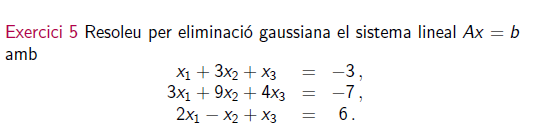

A = [1 3 1; 3 9 4; 2 -1 1]

A =      1     3     1
     3     9     4
     2    -1     1


b = [-3; -7; 6]

b =     -3
    -7
     6


[L,U,P] = lu(A)

L =     1.0000         0         0
    0.6667    1.0000         0
    0.3333   -0.0000    1.0000


U =     3.0000    9.0000    4.0000
         0   -7.0000   -1.6667
         0         0   -0.3333


P =      0     1     0
     0     0     1
     1     0     0



% 1) Ly = Pb
y = forward(L, P*(b))

y =    -7.0000
   10.6667
   -0.6667


% 2) Ux = y
x = backsubs(U,y)

x =     1.0000
   -2.0000
    2.0000



% comprobar residuo

r = b - A*x

r = 	1.0e+-14 *

    0.0444
    0.1776
    0.1776




% opertacion de matlab

A\b

ans =     1.0000
   -2.0000
    2.0000


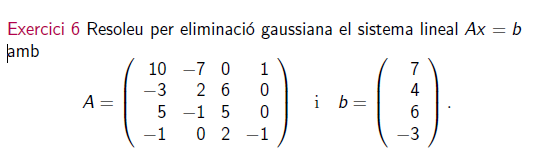

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1]

A =     10    -7     0     1
    -3     2     6     0
     5    -1     5     0
    -1     0     2    -1


b= [7; 4; 6; -3]

b =      7
     4
     6
    -3


[L,U,P] = lu(A)

L =     1.0000         0         0         0
    0.5000    1.0000         0         0
   -0.3000   -0.0400    1.0000         0
   -0.1000   -0.2800    0.5484    1.0000


U =    10.0000   -7.0000         0    1.0000
         0    2.5000    5.0000   -0.5000
         0         0    6.2000    0.2800
         0         0         0   -1.1935


P =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1



% 1) Ly = Pb
y = forward(L, P*(b))

y =     7.0000
    2.5000
    6.2000
   -5.0000


% 2) Ux = y
x = backsubs(U,y)

x =     0.4324
    0.2162
    0.8108
    4.1892



% comprobar residuo

r = b - A*x

r = 	1.0e+-15 *

         0
         0
         0
   -0.8882




% opertacion de matlab

A\b

ans =     0.4324
    0.2162
    0.8108
    4.1892


# Factorització Txoleski

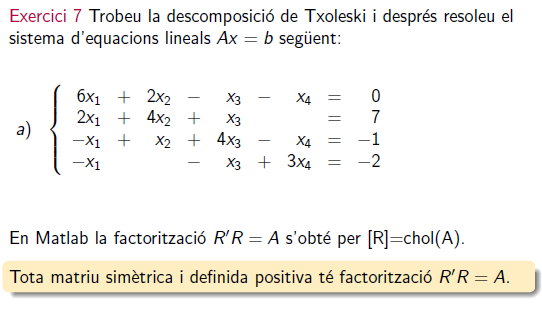

A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3]
b = [0 7 -1 2]'
isequal(A',A)
%R'Rx = b
R = chol(A)

%1) R'y = b
y = forward(R',b)
%2) UX = y 
x = backsubs(R,y)
r = b-A*x
% opertacion de matlab
A\b


# Factorització QR

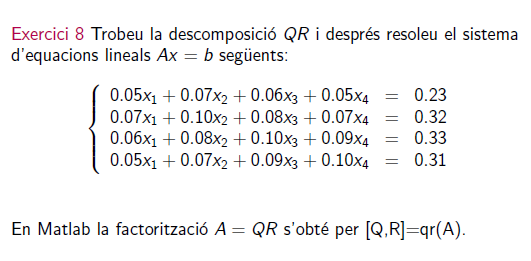

A = [5 7 6 5; 7 10 8 7; 6 8 10 9; 5 7 9 10]/100
b = [23; 32; 33; 32]/100
%Q*R = A
[Q,R] = qr(A)
%1) Rx = Q'b
x = backsubs(R,Q'*b)
%comprobar que el residuo es 0
r = b -A*x


# Vector residu

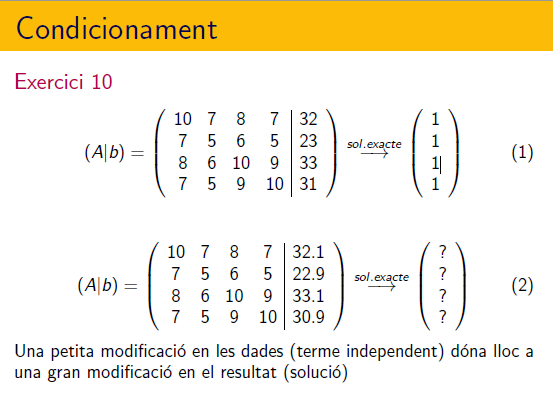

A = [10 7 8 7 ; 7 5 6 5 ; 8 6 10 9; 7 5 9 10]
b = [32 23 33 31]'
bb=[32.1 22.9 33.1 30.9]'
b-bb
norm(b-bb,'inf')
x = A\b
y = A\bb
r = bb-A*y
cond(A),rcond(A), det(A)

%comprobació cota error
c1 = cond(A,'inf')*norm(b-A*y,'inf')/norm(b,'inf')

c2 = norm(x-y, 'inf')/norm(x,'inf')

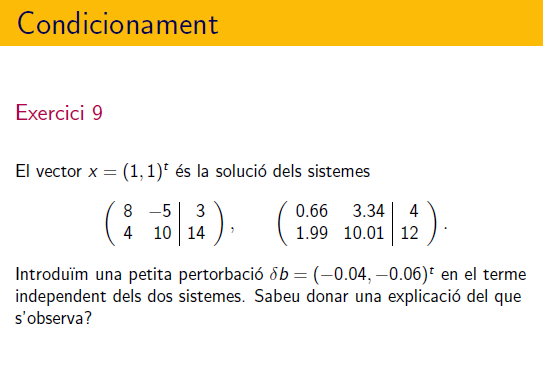

%a)
A= [8 -1; 4 10]
b = [3 14]'
bb = b+[-0.04 -0.06]'
rcond(A), det(A)
x = A\bb, y = A\bb
%b)
A = [0.66 3.34; 1.99 10.01]
b = [4 12]'
bb = b+[-0.04 -0.06]'
rcond(A), det(A)
x = A\bb, y = A\bb

function x = forward(L,x)
% FORWARD. Forward elimination.
% For lower triangular L, x = forward(L,b) solves L*x = b.
[n,n] = size(L);
x(1) = x(1)/L(1,1);
for k = 2:n
   j = 1:k-1;
   x(k) = (x(k) - L(k,j)*x(j))/L(k,k);
end
end

% ------------------------------

function x = backsubs(U,x)
% BACKSUBS.  Back substitution.
% For upper triangular U, x = backsubs(U,b) solves U*x = b.
[n,n] = size(U);
x(n) = x(n)/U(n,n);
for k = n-1:-1:1
   j = k+1:n;
   x(k) = (x(k) - U(k,j)*x(j))/U(k,k);
end
end